Differences in full valid and same filteration

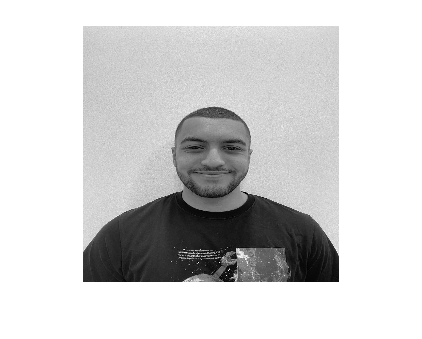

[me,melut] = imread('megray.tif');
figure;
subplot(1,1,1);
imshow(me);

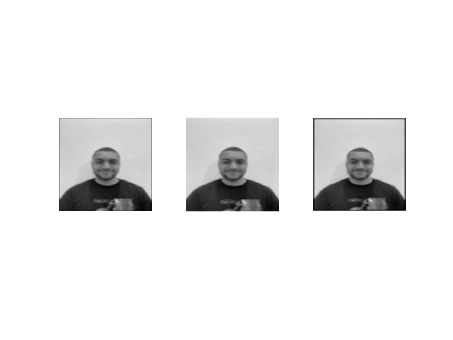


f3 = fspecial("average"	,[5 7]);

filtered_mes = filter2(f3,me,"same");
filtered_mev = filter2(f3,me,"valid");
filtered_mef = filter2(f3,me,"full");

% Dont forget to look at the images sizes since it differs from each
% filtering method

figure;
subplot(1,3,1);
imshow(filtered_mes/255);
subplot(1,3,2);
imshow(filtered_mev/255);
subplot(1,3,3);
imshow(filtered_mef/255);